# Plot M3C Variables

buffer

buffer =   ClassBuffer with properties:

                 Ts: 1.0000e-04
                 Ns: 10000
                  m: 9
                  n: 4
                  A: [6×9 double]
                 is: [9×10000 double]
                ixy: [6×10000 double]
                 iB: [9×10000 double]
                 iz: [9×10000 double]
                 ie: [4×10000 double]
                 vs: [9×10000 double]
                vxy: [6×10000 double]
                 vB: [9×10000 double]
                 vo: [0 0.7477 2.8463 5.9028 9.4870 13.2385 16.8912 20.2686 23.2723 25.8669 28.0646 29.9080 31.4531 32.7553 33.8596 34.7949 35.5739 36.1950 36.6472 36.9143 36.9792 36.8271 36.4469 35.8321 34.9807 33.8949 32.5804 … ] (1×10000 double)
                 Ec: [9×10000 double]
                 vc: [9×10000 double]
            Ec_mean: [422500 4.2250e+05 4.2249e+05 4.2247e+05 4.2245e+05 4.2244e+05 4.2241e+05 4.2239e+05 4.2237e+05 4.2

clf

## is

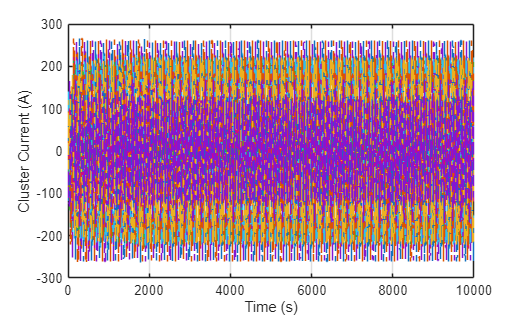

figure
stairs(buffer.is')
hold on
stairs(buffer.is_ref', '--')
hold off
xlabel('Time (s)')
ylabel('Cluster Current (A)')
grid on

## ixy

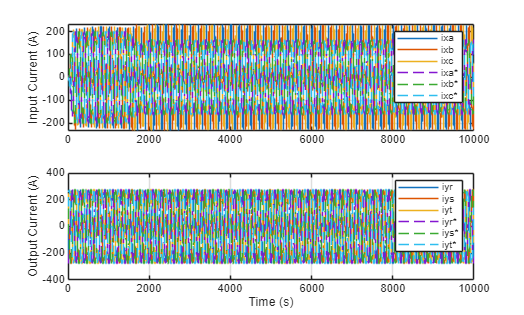

% abc

figure
subplot(2, 1, 1)
stairs(buffer.ixy(1:3, :)')
hold on
stairs(buffer.ixy_ref(1:3, :)', '--')
hold off
legend('ixa', 'ixb', 'ixc', 'ixa*', 'ixb*', 'ixc*')
ylabel('Input Current (A)')
grid on

subplot(2, 1, 2)
stairs(buffer.ixy(4:6, :)')
hold on
stairs(buffer.ixy_ref(4:6, :)', '--')
hold off
legend('iyr', 'iys', 'iyt', 'iyr*', 'iys*', 'iyt*')
ylabel('Output Current (A)')
grid on
xlabel('Time (s)')

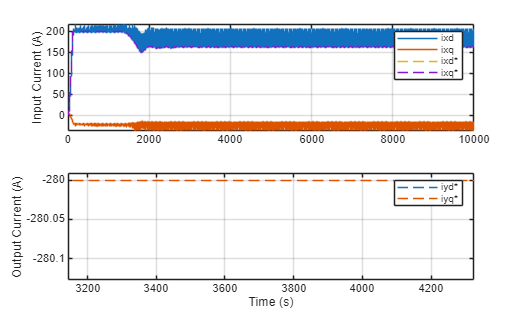


% dq

figure
subplot(2, 1, 1)
stairs(buffer.ixdq')
hold on
stairs(buffer.ixdq_ref', '--')
hold off
legend('ixd', 'ixq', 'ixd*', 'ixq*')
ylabel('Input Current (A)')
grid on

subplot(2, 1, 2)
stairs(buffer.iydq')
hold on
stairs(buffer.iydq_ref', '--')
hold off
legend('iyd', 'iyq', 'iyd*', 'iyq*')
ylabel('Output Current (A)')
grid on

xlabel('Time (s)')

## `iB`

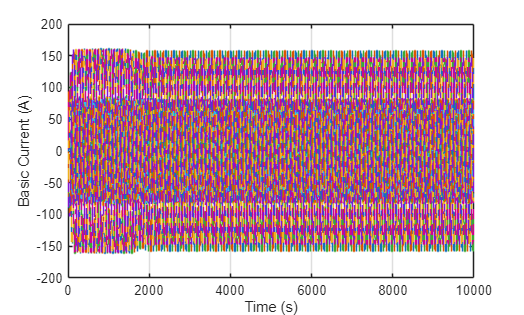

figure
stairs(buffer.iB')
hold on
stairs(buffer.iB_ref', '--')
hold off
xlabel('Time (s)')
ylabel('Basic Current (A)')
grid on

## `iz`

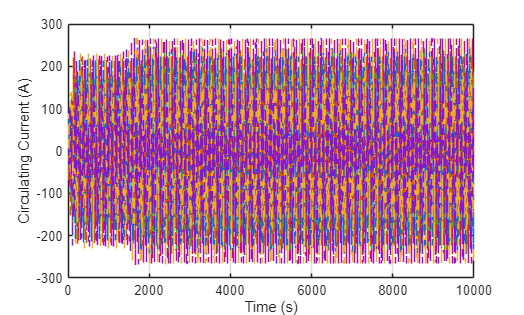

figure
stairs(buffer.iz')
hold on
stairs(buffer.iz_ref', '--')
hold off
xlabel('Time (s)')
ylabel('Circulating Current (A)')
grid on

## `ie`

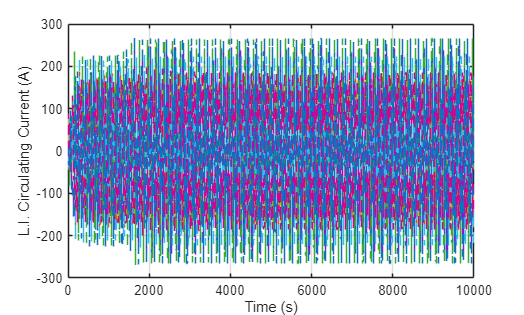

figure
stairs(buffer.ie')
hold on
stairs(buffer.ie_ref', '--')
hold off
xlabel('Time (s)')
ylabel('L.I. Circulating Current (A)')
grid on

## `vs`

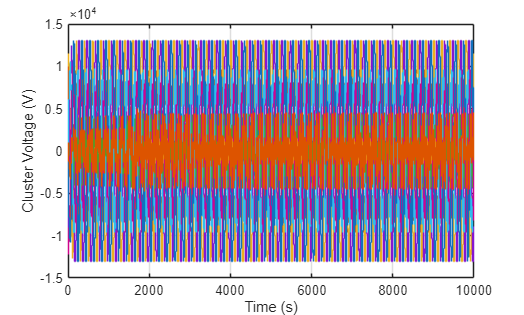

figure
stairs(buffer.vs')
xlabel('Time (s)')
ylabel('Cluster Voltage (V)')
grid on

## `vxy`

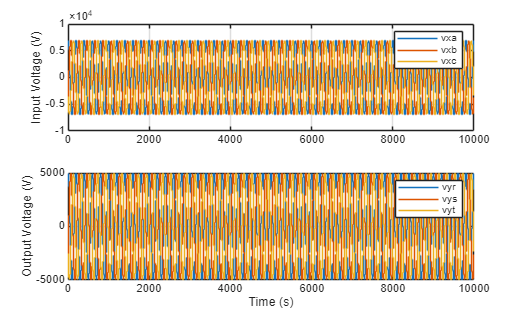

% abc

figure
subplot(2, 1, 1)
stairs(buffer.vxy(1:3, :)')
legend('vxa', 'vxb', 'vxc')
ylabel('Input Voltage (V)')
grid on

subplot(2, 1, 2)
stairs(buffer.vxy(4:6, :)')
legend('vyr', 'vys', 'vyt')
ylabel('Output Voltage (V)')
grid on
xlabel('Time (s)')

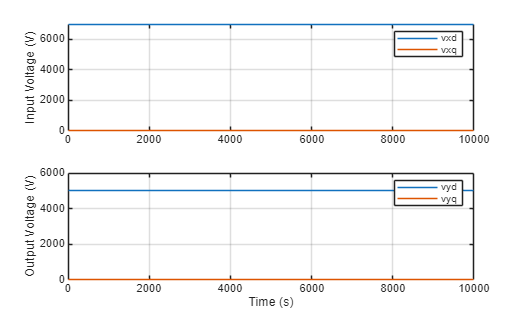


% dq

figure
subplot(2, 1, 1)
stairs(buffer.vxdq')
legend('vxd', 'vxq')
ylabel('Input Voltage (V)')
grid on

subplot(2, 1, 2)
stairs(buffer.vydq')
legend('vyd', 'vyq')
ylabel('Output Voltage (V)')
grid on

xlabel('Time (s)')

## `vB`

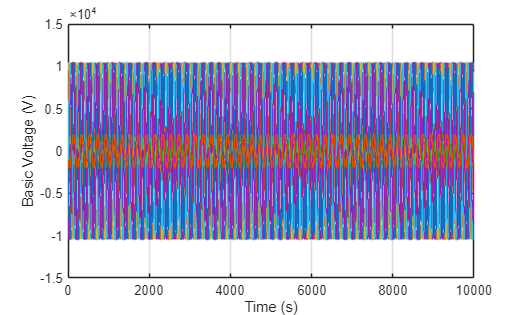

figure
stairs(buffer.vB')
xlabel('Time (s)')
ylabel('Basic Voltage (V)')
grid on

## `vo`

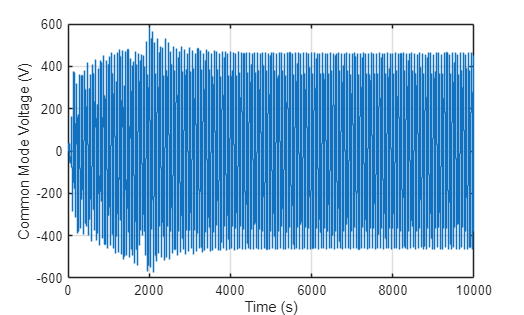

figure
stairs(buffer.vo')
xlabel('Time (s)')
ylabel('Common Mode Voltage (V)')
grid on

## `Ec`

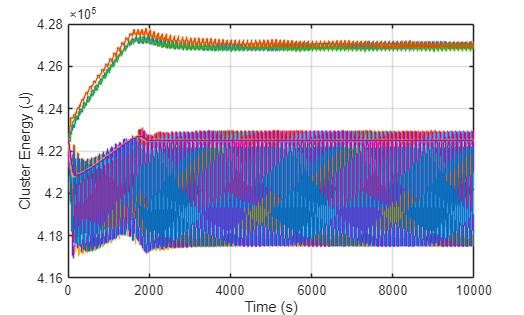

figure
stairs(buffer.Ec')
hold on
stairs(buffer.Ec_mean')
stairs(buffer.Ec_mean_filt')
hold off
ylabel('Cluster Energy (J)')
xlabel('Time (s)')
grid on

## `vc`

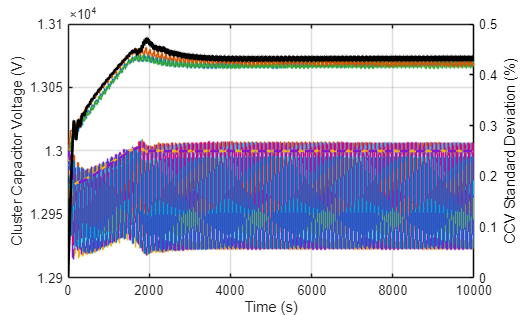

figure

stairs(buffer.vc')
hold on
stairs(buffer.vc_mean', '--', 'LineWidth', 2)
stairs(buffer.vc_mean_filt', '--', 'LineWidth', 2)
hold off
ylabel('Cluster Capacitor Voltage (V)')

yyaxis right
stairs(100*std(buffer.vc./buffer.vc_mean)', 'LineWidth', 2, 'Color', 'black')
ylabel('CCV Standard Deviation (%)')
ax = gca;
ax.YAxis(2).Color = 'black';
ax.YColor = 'black';

xlabel('Time (s)')
grid on

## TEB PI

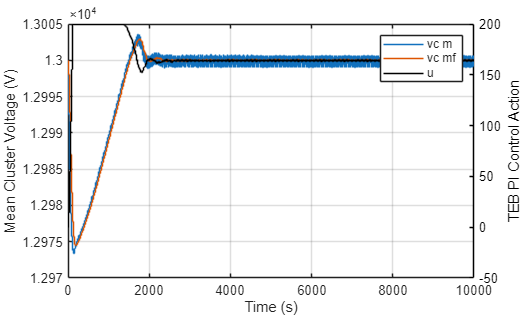

figure

stairs(buffer.vc_mean')
hold on
stairs(buffer.vc_mean_filt')
hold off
ylabel('Mean Cluster Voltage (V)')

yyaxis right
stairs(buffer.u_TEB', 'Color', 'black')
ylabel('TEB PI Control Action')
ax = gca;
ax.YAxis(2).Color = 'black';
ax.YColor = 'black';

legend('vc m', 'vc mf', 'u')
xlabel('Time (s)')
grid on

## Input PLL

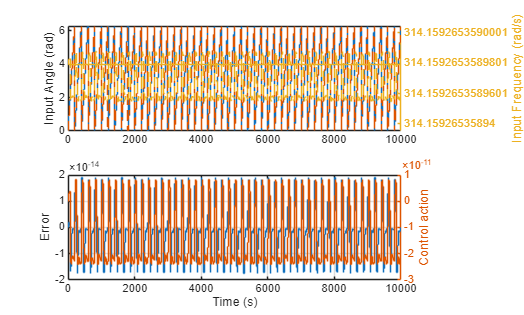

figure

% Estimations
subplot(2, 1, 1)

% Angle
stairs(buffer.gx')
hold on
stairs(buffer.gx_pll', '--')
hold off
ylabel('Input Angle (rad)')

% Frequency
yyaxis right
stairs(buffer.wx')
hold on
stairs(buffer.wx_pll', '--')
hold off
ylabel('Input Frequency (rad/s)')

% Performance
subplot(2, 1, 2)

% Error
stairs(buffer.ex_pll')
ylabel('Error')

% Control action
yyaxis right
stairs(buffer.ux_pll')
ylabel('Control action')

xlabel('Time (s)')
grid on

## Output PLL

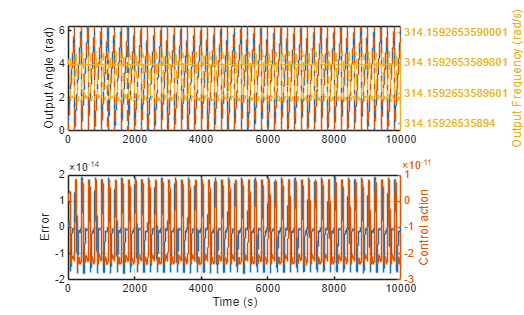

figure

% Estimations
subplot(2, 1, 1)

% Angle
stairs(buffer.gy')
hold on
stairs(buffer.gy_pll', '--')
hold off
ylabel('Output Angle (rad)')

% Frequency
yyaxis right
stairs(buffer.wy')
hold on
stairs(buffer.wy_pll', '--')
hold off
ylabel('Output Frequency (rad/s)')

% Performance
subplot(2, 1, 2)

% Error
stairs(buffer.ey_pll')
ylabel('Error')

% Control action
yyaxis right
stairs(buffer.uy_pll')
ylabel('Control action')

xlabel('Time (s)')
grid on

## Exit Flags

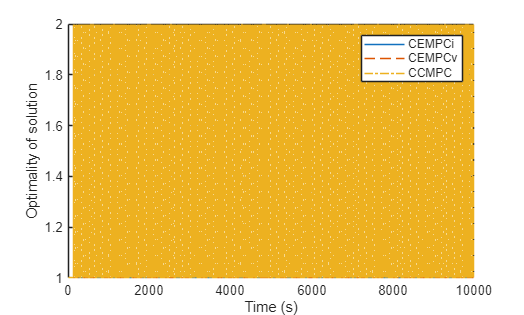

figure
stairs(buffer.exitflag_CEMPCi', '-')
hold on
stairs(buffer.exitflag_CEMPCv', '--')
stairs(buffer.exitflag_CCMPC', '-.')
hold off
ylabel('Optimality of solution')
xlabel('Time (s)')
legend('CEMPCi', 'CEMPCv', 'CCMPC')
grid on

## Active Constraints

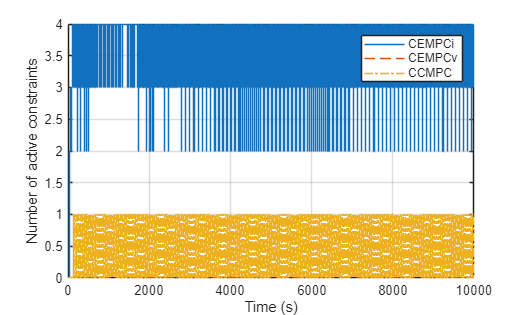

figure
stairs(buffer.iA_CEMPCi', '-')
hold on
stairs(buffer.iA_CEMPCv', '--')
stairs(buffer.iA_CCMPC', '-.')
hold off
ylabel('Number of active constraints')
xlabel('Time (s)')
legend('CEMPCi', 'CEMPCv', 'CCMPC')
grid on

## Controller Execution Time

figure
stairs(buffer.Tex_CEMPC'*1000)
ylabel('CEMPC execution time (ms)')
xlabel('Time (s)')
grid on

figure
stairs(buffer.Tex_CCMPC'*1000)
ylabel('CCMPC execution time (ms)')
xlabel('Time (s)')
grid on